%test functions
f = @(t) sin(2*pi*2*t)./(3 + sin(2*pi*t))

f = function_handle with value:
    @(t)sin(2*pi*2*t)./(3+sin(2*pi*t))


g = @(t) 2*sin(2*16*pi*t)+0.1*sin(2*4*pi*t)+sin(2*23*pi*t)+sin(2*12*pi*t)

g = function_handle with value:
    @(t)2*sin(2*16*pi*t)+0.1*sin(2*4*pi*t)+sin(2*23*pi*t)+sin(2*12*pi*t)



%defining variables
Fs = 100;
T = 3;
[x, t] = sampling2n(g, Fs, T);
n = length(x)

n = 256

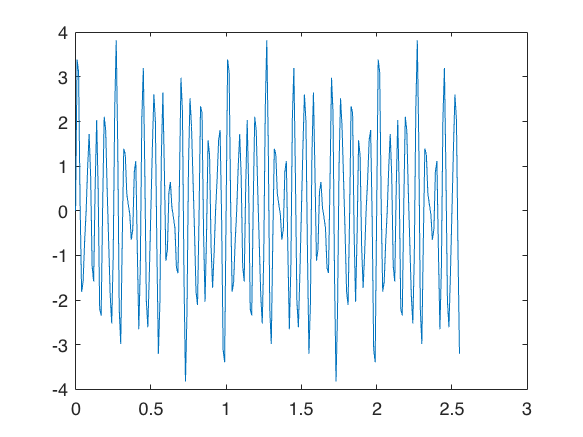

plot(t, x)  



f = Fs/n.*(0:(n-1)/2)  %frequency vector 

f =          0    0.3906    0.7812    1.1719    1.5625    1.9531    2.3438    2.7344    3.1250    3.5156    3.9062    4.2969    4.6875    5.0781    5.4688    5.8594    6.2500    6.6406    7.0312    7.4219    7.8125    8.2031    8.5938    8.9844    9.3750    9.7656   10.1562   10.5469   10.9375   11.3281   11.7188   12.1094   12.5000   12.8906   13.2812   13.6719   14.0625   14.4531   14.8438   15.2344   15.6250   16.0156   16.4062   16.7969   17.1875   17.5781   17.9688   18.3594   18.7500   19.1406


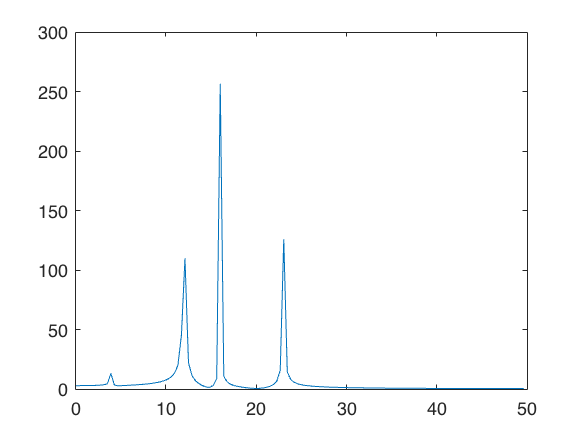


y = Myfft(x);   %using my fft function 

plot(f, abs(y(1, 1:n/2)))%plotting left half of the fft 




%[a,b] = dft(x);
%
%A = sqrt(a.^2+b.^2);  % amplitudes
%K = length(A);
%v = (0:K-1) / T; % alternative formula for v
%plot(v,A)
%title('magnitude spectrum of x')
%xlabel('frequency (Hz)'), ylabel('amplitude')
%
%
%x1 = fft(x)
%